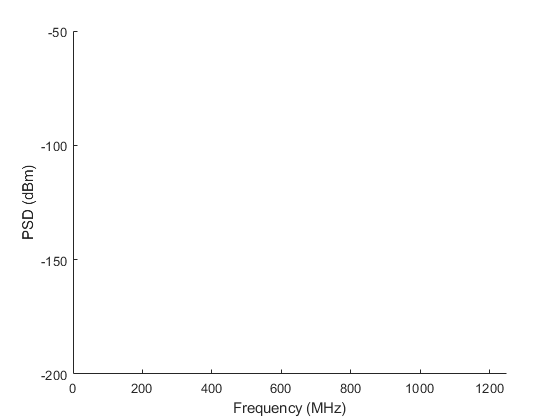

%% introduction
% ************************************************************************
% batch process captured waveforms to compute SNR
% *************************************************************************
% working enviroment: Matlab 2008b and above
% Author: Liu Zhixin @ UCL
% Date created: Nov.02, 2021
% Date of last major modification: Nov.15, 2021
% copyright @ Zhixin Liu, all rights reserved,
% CC-BY, for teaching and education
% *************************************************************************
clc; clear; close all;format long;
% data path - change this to your own data path (suggest use your own onedrive)
datapath = 'testdata\SNR\';
%% SNR characterisation (use your own script, NOT the MATLAB build-in functions)
bandwidth = 100e3; % signal tone bandwidth [Hz]
Vpp = 2:9; % [mV]
SNR = zeros(size(Vpp));
for i = 1:numel(Vpp)
% load waveform
waveform_filename = sprintf('task2_%.1dmV.CSV', Vpp(i));
waveform_filename = strcat(waveform_filename);
data = csvread(waveform_filename,1,0);
% get waveform info
T = data(:,1); % time [s]
Waveform = data(:,2) - mean(data(:,2)); % amplitude with AC blocked [V]
dt = 4e-10; % sampling period
fs = 1/dt; % sampling rate
N = 100000; % number of samples
df = fs/N; % bandwidth of each frequency bin
f = (0:N/2-1).' * (fs / N); % frequency array

% calculate PSD
% calculate the Fourier transform of the complex envelope
Ampf = fft(Waveform) * dt;
% calculate the real and img part

absAmpf = abs(Ampf(1:N/2));
% Then calculate the single-side band PSD (W/Hz)
psd = absAmpf.^(2)/dt*2;


% find the signal frequency
[peakPSD, index] = max(psd);
% signal centre frequency frequency
f_sig = (index-1) * df;
% signal psd
psd_sig = psd(f>f_sig-bandwidth/2 & f<f_sig+bandwidth/2);
% noise psd
psd_noise = psd(f<f_sig-bandwidth/2 | f>f_sig+bandwidth/2);
% show signal and noise separately with 'dBm' as y-axis
figure;

psd_sig_dBm = 10*log10(psd_sig*1000);
psd_noise_dBm = 10*log10(psd_noise*1000);
% plot signal PSD
% plot(f(1:N/2)/1e6, psd_sig_dBm);
% plot noise PSD
% plot(f(1:N/2)/1e6, psd_noise_dBm);


xlabel('Frequency (MHz)'); ylabel('PSD (dBm)'); axis([0 fs/2/1e6 -200 -50]);
drawnow
% SNR calculation
sig_power = sum(psd_sig)*df; % signal power
noise_power = sum(psd_noise)*df; % noise power
SNR(i) = 10*log10(sum(sig_power)/sum(noise_power)); % [dB]
end

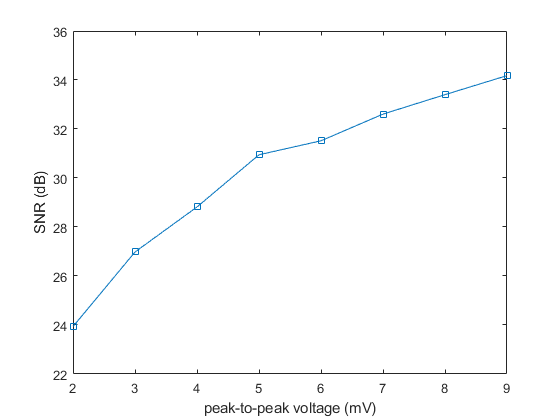

% --- plot SNR vs Vpp ---
figure; 
plot(Vpp,SNR,'-s');
xlabel('peak-to-peak voltage (mV)');
ylabel('SNR (dB)');